# **EN2073 - Analog and Digital Communications**

## **Assignment 1**

## **Name : Rathnayaka R.G.H.V.**

## **Index Number : 180529E**

# 1. Plot of y(t)

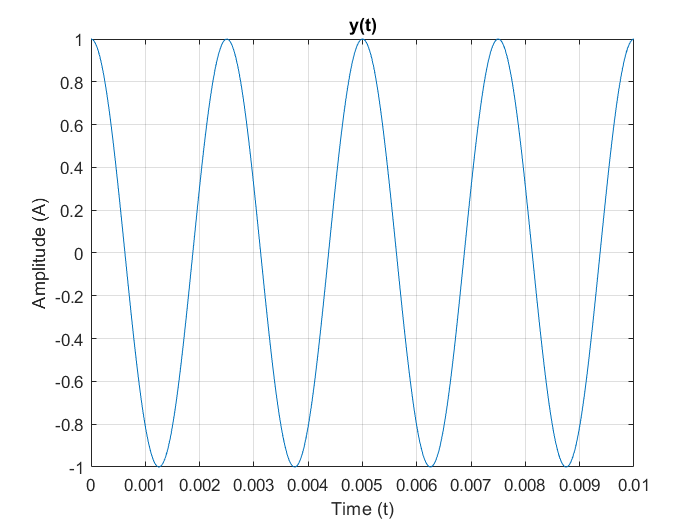

%%1.Plot of y(t)
%%
f = 400; % frequency (Hz)
A = 1; % Amplitude (a.u)
t_lim= 0.01; % Time limit (s)
t = linspace(0,t_lim,1000);
y_t = A*cos(2*pi*f*t); % Required function
figure;
plot(t,y_t); % Plot for y(t)
xlabel('Time (t)');
ylabel('Amplitude (A)');
title('y(t)');
grid on;

# 2. Nyquist sampling frequency (fnq)

f_nq = 2*f; % Nyquist sampling frequency
fprintf('Nyquist sampling frequency = %d Hz', f_nq);

Nyquist sampling frequency = 800 Hz

# 3. Ideal sampling the signal at Nyquist sampling rate (fnq)

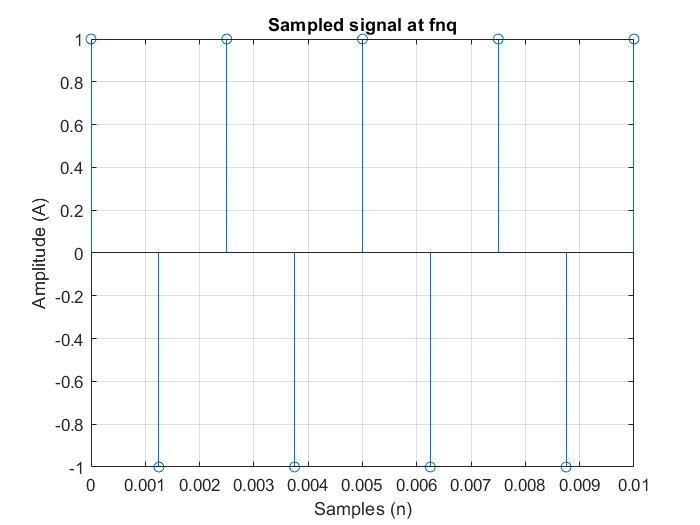

f = 400; % frequency (Hz)
A = 1; % Amplitude (a.u)
t_lim= 0.01; % Time limit (s)

figure;
stem(n1,y_n1);
xlabel('Samples (n)');
ylabel('Amplitude (A)');
title('Sampled signal at fnq');
grid on;

# 4.Sampling the signal at 2 times Nyquist sampling rate (fnq) & at one-half of Nyquist sampling rate (fnq)

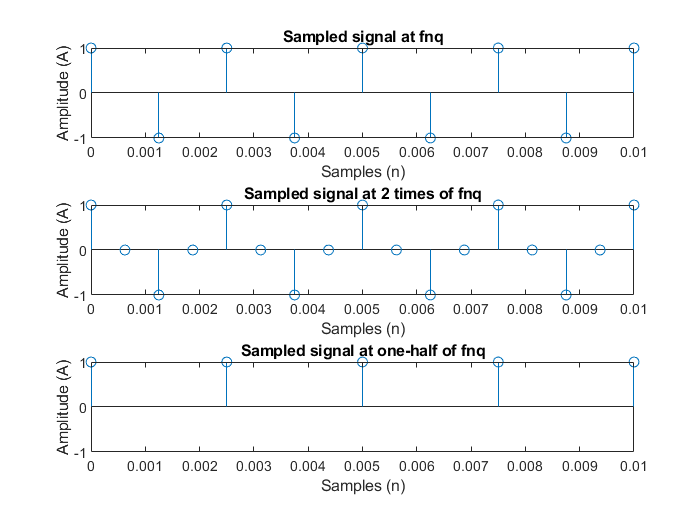

f_nq = 2*f; % Nyquist frequency
[n1,y_n1] = sampling(f_nq,t_lim,A,f); % Ideal sampling at Nyquist sampling rate
[n2,y_n2] = sampling(2*f_nq,t_lim,A,f); % Sampling at 2 times Nyquist sampling rate
[n3,y_n3] = sampling(0.5*f_nq,t_lim,A,f); % Sampling at one-half of Nyquist sampling rate
titles = ['Sampled signal at twice of fnq','Sampled signal at one-half of fnq'];
figure;
subplot(3,1,1);
stem(n1,y_n1); % Plotting the sampled signal at Nyquist sampling frequency
xlabel('Samples (n)');
ylabel('Amplitude (A)');
ylim([-A,+A]);
title('Sampled signal at fnq');
subplot(3,1,2);
stem(n2,y_n2); % Plotting the sampled signal at 2 times Nyquist sampling frequency
xlabel('Samples (n)');
ylabel('Amplitude (A)');
ylim([-A,+A]);
title('Sampled signal at 2 times of fnq');
subplot(3,1,3);
stem(n3,y_n3); % Plotting the sampled signal at one-half of Nyquist sampling frequency
xlabel('Samples (n)');
ylabel('Amplitude (A)');
ylim([-A,+A]);
title('Sampled signal at one-half of fnq');

**Observations :** 

- The above three plots show the ideally sampled signal at the Nyquist rate, sampled signal at twice of Nyquist rate and the the sampled at one-half of Nyquist rate.

- The ideally sampled signal which was sampled at the Nyquist rate, shows only the minimum and maximum points. So, we can predict the original signal to some extent.

- The sampled signal at twice of the Nyquist rate shows mid values in addition to the minimum and the maximumpoints represented by the ideally samped signal. Although the mid values are zero, it will be benificial in discovering the original signal from the sampled signal. This give a high accuracy than the earlier situation.

- It is unable to discover the origiinal signal from the sampled signal at one-half of the Nyquist rate as there are only the maximum points in the sampled signal.

- **So, as a whole if the frequency of the sampled signal (f_s) = Nyquist sampling rate (f_nq), it is able to recover the original signal, if the frequency of the sampled signal (f_s) > Nyquist sampling rate (f_nq), it is very easy to recover the original signal with a high accuracy and if the frequency of the sampled signal  (f_s) < Nyquist sampling rate (f_nq), it is unable to recover the original signal.    **              

# 5.The minimum number of bits (nb) required per a sample and number of minimum quantization levels (L) required.


$$Signal Power=\;\frac{A^2 }{2}$$



$$Q Noise Power=\frac{\textrm{∆}A^2 }{12}$$


since $\textrm{∆}A=\frac{2A}{\left(L-1\right)}$ ,  $Q Noise Power=\frac{A^2 }{3{\left(L-1\right)}^2 }$


$$SNqR = 10\;log{\left(\frac{Signal Power}{Q Noise Power}\right)}$$



$$SNqR = 10\;log{\left(\frac{\frac{A^2 }{2}}{\frac{A^2 }{3{\left(L-1\right)}^2 }}\right)}$$

$$\;=10\;log{\left(\frac{3{\left(L-1\right)}^2 }{2}\right)}$$


In order to exist a $S\textrm{N}q\textrm{R}$ ratio greater than 25dB,

$S\textrm{N}q\textrm{R}$ >   25dB

$10\;\mathrm{lo}g{\left(\frac{3{\left(L-1\right)}^2 }{2}\right)}$ >   25

$log{\left(\frac{3{\left(L-1\right)}^2 }{2}\right)}$ >     2.5

${\left(\frac{3{\left(L-1\right)}^2 }{2}\right)}$ >   10^2.5

$\;\;\;\;\;\;\;\;\;\;\;\;\;\;L-1$   >    14.5196

                
$$L\;\;\;\;\;\;>\;\;\;\;15\ldotp 5196$$


L is an interger.

Therefore, **the minimum number of quantization levels (L) required is 16.**

As $2^{\mathrm{nb}} \ge L$,


$$\mathrm{nb}\;\ge \;4$$


**The minimum number of bits (nb) required is 4**.

# 6.matlab function to take a sampled value, number of quantization levels (L) and range (maximum amplitude) and to output the quantized value

function quantized_value = quantizing(y,L,A)
    delta = 2*A/(L-1); % Gap between two quantization levels
    if y == A & (mod(y,delta) == 0);
        quantized_value = y - (mod(y,delta)) - delta/2;
    else
        quantized_value = y - (mod(y,delta)) + delta/2;
    end
end

## Defining a function for calculating sampled signal

function [n,y_s] = sampling(f_s,t_lim,A,f)
    T_s = 1/f_s; % Calculating the period
    n = 0:T_s:t_lim; % Calcuating the number of periods
    y_s = A*cos(2*pi*f*n); % Calculating sampled function
end
